# Basic Tight-Binding Theory - Part 3

## Example 3: The brick lattice

The brick lattice is topologically similar to that of the graphene lattice. As its name suggests, it is a 2D lattice that exhibits a pattern of stacked bricks. We will consider two sites per unit cell. Defining the geometry of such a system is simple


$$\[
\mathbf{a}_1 = (a,a,0),\ \mathbf{a}_2 = (a,-a,0)
\]
\[
\mathbf{b}_1 = (\pi/a,\pi/a,0),\ \mathbf{b}_2 = (\pi/a,-\pi/a,0)
\]$$


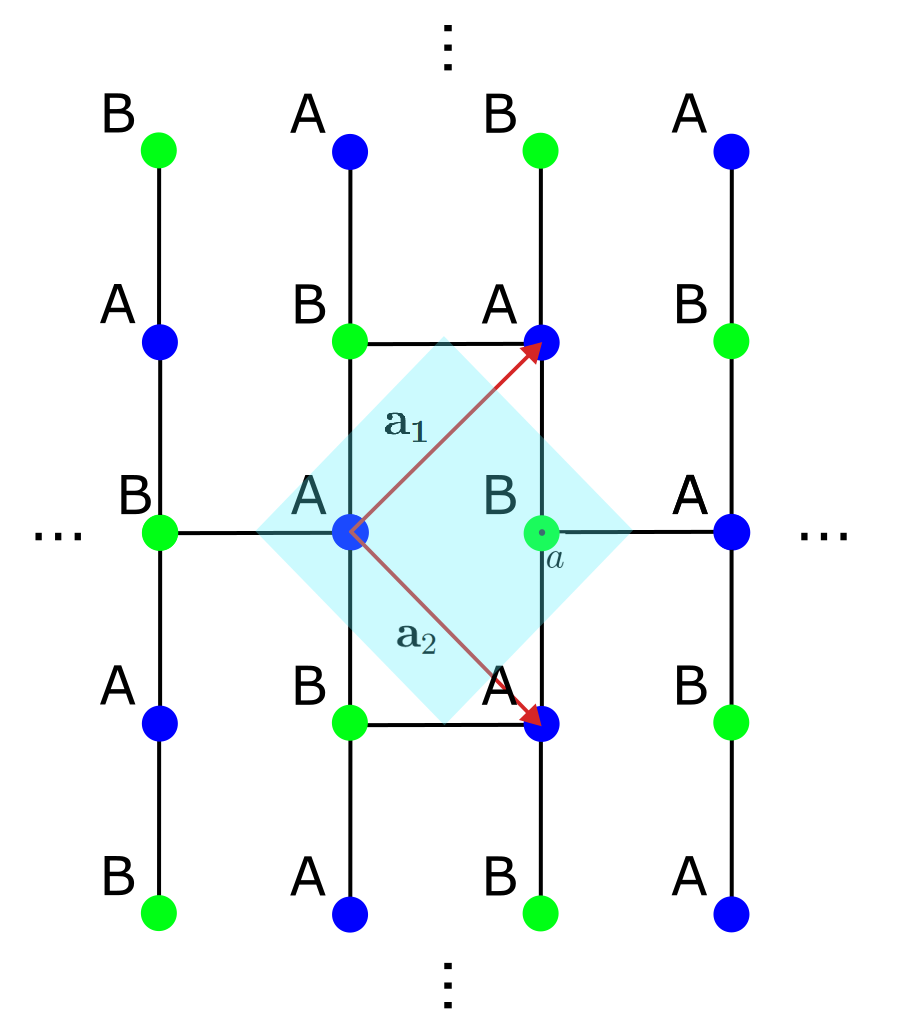

Now, we define the NN vectors $\{\mathbf{d}_n\}$, for which there are three NNs


$$\[
\mathbf{d}_1 = (a,0,0),\ \mathbf{d}_2 = (0,a,0),\ \mathbf{d}_3 = (0,-a,0) = - \mathbf{d}_2
\]$$


Writing down the Hamiltonian 


$$\[
H = u_A \sum_i a_i^\dag a_i + u_B \sum_j b_j^\dag b_j + t \sum_{i, j} (a_i^\dag b_j+ \textbf{h.c.})
\]$$


Like we did before, changing basis to $k$-space, and setting $u_A = u_B = u$, we get 


$$\[
H = \sum_k 
\left(
\begin{array}{cc}
    a_k^\dag & b_k^\dag
\end{array}
\right)
\left(
\begin{array}{cc}
    u & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u
\end{array}
\right)
\left(
\begin{array}{cc}
    a_k \\
    b_k
\end{array}
\right)
\]$$



$$\[
f(\mathbf{k}) \equiv \sum_{n=1}^{3} e^{i(\mathbf{k}\cdot \mathbf{d}_n)} = e^{i(\mathbf{k}\cdot \mathbf{d}_1)} + e^{i(\mathbf{k}\cdot \mathbf{d}_2)} + e^{i(\mathbf{k}\cdot \mathbf{d}_3)} 
= e^{i k_x a} + e^{i k_y a} + e^{-i k_y a} = e^{i k_x a} + 2 \cos(k_y a)\]$$


Evidently,


$$\[
\tilde{H} \equiv 
\left(
\begin{array}{cc}
    u & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u
\end{array}
\right)
\]
\[\Rightarrow \det(\tilde{H} - \mathbb{I}E)=
\det\left(
\begin{array}{cc}
    u-E & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u-E
\end{array}
\right)
= (E-u)^2 - t^2 |{f(\mathbf{k})}|^2 = (E-u)^2 - t^2 \bigl|e^{i k_x a} + 2 \cos(k_y a)\bigl|^2 = 0
\]
\[
= (E-u)^2 - t^2 \biggr[4 \cos^2(k_y a) + 4 \cos(k_x a) \cos(k_y a) + 1\biggr]

= (E-u)^2 - t^2 \biggr[2 \cos(2 k_y a) + 2 + 4 \cos(k_x a) \cos(k_y a) + 1\biggr]
\]
\[
= (E-u)^2 - t^2 \biggr[2 \cos(2 k_y a) + 4 \cos(k_x a) \cos(k_y a) + 3\biggr] = 0
\]
\[
\therefore E(\mathbf{k}) = u \pm t \sqrt{4 \cos(k_x a) \cos(k_y a) + 2 \cos(2 k_y a) + 3}
\]$$


By definition, the high-symmetry points of a brick lattice of two sites per unit cell in momentum space are


$$\[
\Gamma = (0,0,0);\ M = X = (\pi/a,0,0);\ Y = (0,\pi/a,0);\ K' = \biggl(0, \frac{2\pi}{3 a}, 0\biggl),
\]$$


and the k-path will be $\Gamma \rightarrow M \rightarrow Y \rightarrow K' \rightarrow \Gamma$.

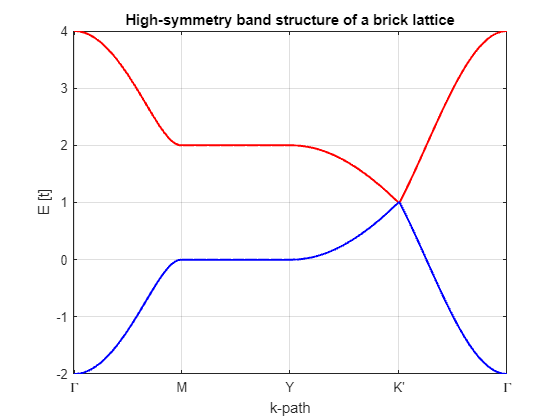

u = 1; % units of t

% Define the eigen-energy as a function of kxa and kya
E1 = @(kxa, kya) 1 + sqrt(4*cos(kxa).*cos(kya) + 2*cos(2*kya) + 3); % In units of t
E2 = @(kxa, kya) 1 - sqrt(4*cos(kxa).*cos(kya) + 2*cos(2*kya) + 3); % In units of t

N = 100; % number of points along each segment

% Define the high symmetry points
G = [0, 0];   % units of a
M = [pi, 0];      % units of a
Y = [0, pi];      % units of a
Kp = [0, 2*pi/3]; % units of a

% Interpolate between points
k_Gamma_X = [linspace(G(1), M(1), N)', linspace(G(2), M(2), N)'];
k_X_Y = [linspace(M(1), Y(1), N)', linspace(M(2), Y(2), N)'];
k_Y_K6 = [linspace(Y(1), Kp(1), N)', linspace(Y(2), Kp(2), N)'];
k_K6_Gamma = [linspace(Kp(1), G(1), N)', linspace(Kp(2), G(2), N)'];

% Combine the paths
k_path = [k_Gamma_X; k_X_Y; k_Y_K6; k_K6_Gamma];

% Calculate the energy along the path
E_path1 = E1(k_path(:,1), k_path(:,2));
E_path2 = E2(k_path(:,1), k_path(:,2));

% Plot the band structure over the high-symmetry path
figure
plot(E_path1, 'r', 'LineWidth', 1.5) 
hold on
plot(E_path2, 'b', 'LineWidth', 1.5)
xticks([1, N, 2*N, 3*N, 4*N]) % Mark the high-symmetry points
xticklabels({'\Gamma', 'M', 'Y', 'K''', '\Gamma'})
xlabel("k-path");
ylabel("E [t]");
title('High-symmetry band structure of a brick lattice');
grid on
hold off

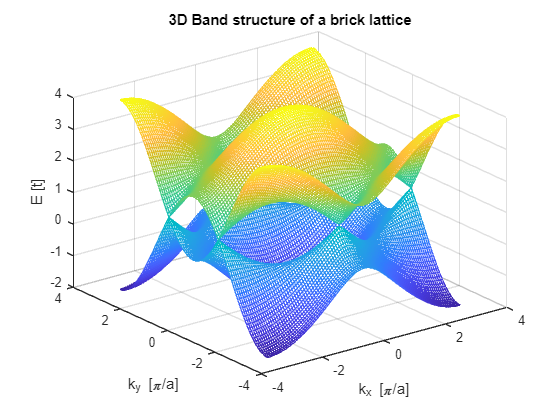

% Define the k-mesh 
[mkxa,mkya] = meshgrid(linspace(-pi,pi),linspace(-pi,pi));

% 3D plot of the eigen-energy function 
mesh(mkxa, mkya, E1(mkxa, mkya));
hold on;
mesh(mkxa, mkya, E2(mkxa, mkya));
xlabel ("k_x [\pi/a]");
ylabel ("k_y [\pi/a]");
zlabel ("E [t]");
title('3D Band structure of a brick lattice');